%% ============================================================
% SINGLE PHOTON CAMERA REAL DATA RECONSTRUCTION
%
% Mirror Position
%       ->
% SPC Frame
%       ->
% Background Correction
%       ->
% SINGLE-POINT STAR DETECTION
%
% The star is represented by ONE point at the maximum
% background-corrected photon count.
% ============================================================

clear; clc; close all


%% ============================================================
% READ PHOTON COUNT CSV
% ============================================================

folder = '\\userfs\bh1308\w2k\Desktop\Single Photon Camera\CSV';

filename = uigetfile( ...
    fullfile(folder,'*.csv'), ...
    'Select Photon Scan File');

if isequal(filename,0)
    error('No file selected.');
end

data = readtable( ...
    fullfile(folder,filename));


%% ============================================================
% EXTRACT DATA
% ============================================================

mirrorX = data.X;
mirrorY = data.Y;
Counts  = data.Count;


%% ============================================================
% SCAN PARAMETERS
% ============================================================

Nx = 25;
Ny = 25;


%% ============================================================
% CONVERT MIRROR POSITIONS TO PIXEL POSITIONS
% ============================================================

x_grid = linspace( ...
    min(mirrorX), ...
    max(mirrorX), ...
    Nx);

y_grid = linspace( ...
    min(mirrorY), ...
    max(mirrorY), ...
    Ny);


SPC_counts = zeros(Ny,Nx);
SPC_visits = zeros(Ny,Nx);


for k = 1:length(Counts)

    [~,x_index] = ...
        min(abs(x_grid - mirrorX(k)));

    [~,y_index] = ...
        min(abs(y_grid - mirrorY(k)));


    % Accumulate counts
    SPC_counts(y_index,x_index) = ...
        SPC_counts(y_index,x_index) + Counts(k);


    % Count measurements
    SPC_visits(y_index,x_index) = ...
        SPC_visits(y_index,x_index) + 1;

end


%% ============================================================
% CALCULATE AVERAGE WHERE MEASUREMENTS EXIST
% ============================================================

SPC_frame = zeros(Ny,Nx);

valid = SPC_visits > 0;

SPC_frame(valid) = ...
    SPC_counts(valid) ./ SPC_visits(valid);


%% ============================================================
% SAVE RAW IMAGE
% ============================================================

SPC_frame_raw = SPC_frame;


%% ============================================================
% CALCULATE BACKGROUND THRESHOLD
% ============================================================

backgroundCounts = Counts;

backgroundmedian = median(backgroundCounts);

sigma = std(backgroundCounts);

k_threshold = -1;

threshold = ...
    backgroundmedian + k_threshold*sigma;


fprintf('\n')
fprintf('========================================\n')

fprintf('BACKGROUND CALCULATION\n')

BACKGROUND CALCULATION


fprintf('========================================\n')


fprintf('Background Median = %.2f\n', ...
    backgroundmedian);

Background Median = 65.00



fprintf('Background SD     = %.2f\n', ...
    sigma);

Background SD     = 32.69



fprintf('Threshold         = %.2f\n', ...
    threshold);

Threshold         = 32.31




%% ============================================================
% BACKGROUND CORRECTION
% ============================================================

Photon_image = ...
    max(SPC_frame_raw - threshold,0);


%% ============================================================
% FIND SINGLE STAR POINT
% ============================================================

% Find location of maximum photon count

[maxCount,linearIndex] = ...
    max(Photon_image(:));


% Convert linear index to row and column

[starY,starX] = ...
    ind2sub(size(Photon_image),linearIndex);


%% ============================================================
% CONVERT STAR PIXEL TO MIRROR POSITION
% ============================================================

starMirrorX = ...
    x_grid(starX);

starMirrorY = ...
    y_grid(starY);


%% ============================================================
% PRINT STAR POSITION
% ============================================================

fprintf('\n')
fprintf('========================================\n')

fprintf('SINGLE-POINT STAR DETECTION\n')

SINGLE-POINT STAR DETECTION


fprintf('========================================\n')


fprintf('Maximum corrected count = %.2f\n', ...
    maxCount);

Maximum corrected count = 295.69



fprintf('Pixel X = %d\n', ...
    starX);

Pixel X = 18



fprintf('Pixel Y = %d\n', ...
    starY);

Pixel Y = 16



fprintf('Mirror X = %.6f\n', ...
    starMirrorX);

Mirror X = 0.102831



fprintf('Mirror Y = %.6f\n', ...
    starMirrorY);

Mirror Y = 0.062537


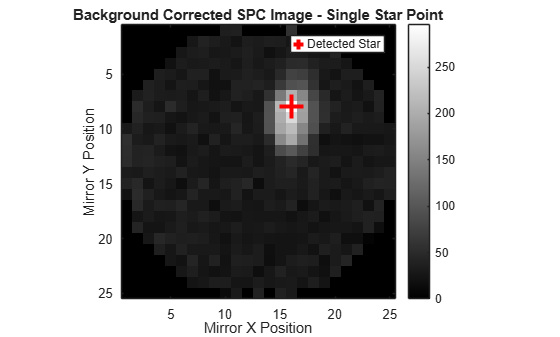



%% ============================================================
% DISPLAY BACKGROUND CORRECTED IMAGE
% ============================================================

figure

imagesc(rot90(Photon_image))

axis image
axis ij

colormap(gray)
colorbar

hold on


%% ============================================================
% CORRECT COORDINATES FOR rot90()
% ============================================================

displayX = starY;

displayY = ...
    Nx - starX + 1;


%% ============================================================
% PLOT SINGLE STAR POINT
% ============================================================

plot( ...
    displayX, ...
    displayY, ...
    'r+', ...
    'MarkerSize',18, ...
    'LineWidth',3);


title('Background Corrected SPC Image - Single Star Point')

xlabel('Mirror X Position')
ylabel('Mirror Y Position')

legend('Detected Star')

hold off

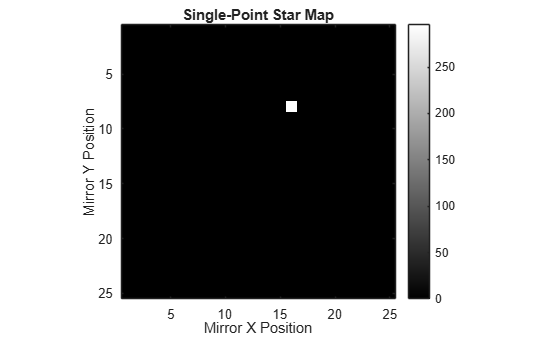



%% ============================================================
% CREATE SINGLE-POINT IMAGE
% ============================================================

Star_point_image = zeros(Ny,Nx);

Star_point_image(starY,starX) = ...
    maxCount;


%% ============================================================
% DISPLAY SINGLE-POINT STAR
% ============================================================

figure

imagesc(rot90(Star_point_image))

axis image
axis ij

colormap(gray)
colorbar

title('Single-Point Star Map')

xlabel('Mirror X Position')
ylabel('Mirror Y Position')

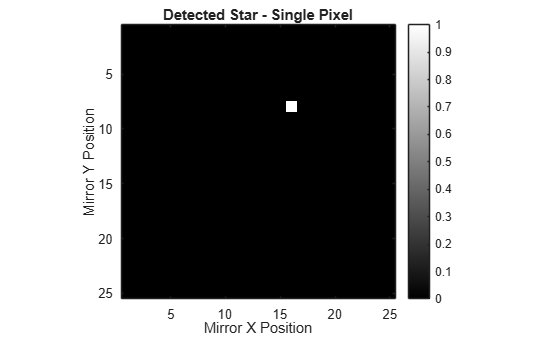



%% ============================================================
% DISPLAY SINGLE POINT AS BINARY MAP
% ============================================================

Star_binary = zeros(Ny,Nx);

Star_binary(starY,starX) = 1;


figure

imagesc(rot90(Star_binary))

axis image
axis ij

colormap(gray)
colorbar

title('Detected Star - Single Pixel')

xlabel('Mirror X Position')
ylabel('Mirror Y Position')